# Cost Function Tests 

We test the cost functions so that we know they work for the given inputs.

The inputs to all the cost functions vary, especially those with aerodynamic cost functions, but we can first determine some basic cost functions, such as wing-area over time and volume subtended by the wing over time. Also flapping to filding ratios and spans over time using simple geometry.

#### Generate wing motion test data

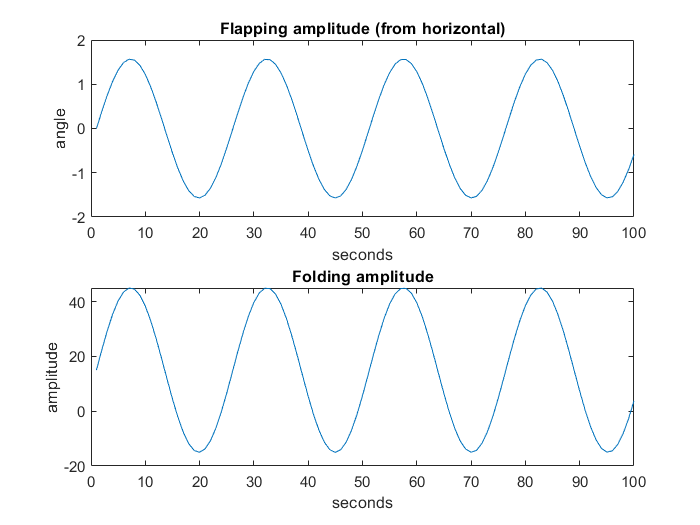

%create the basic wing shapes with the connectivity matricies
wingShape = CreateBasicWingShape();

%define the alpha and beta parameters, those being the wing folding
%amplitude and wing flapping angle
%timesteps
t = 0:1:99;

%set of flapping angles
angles = (pi/2)*sin(0.25*t);

%set of folding amplitudes (for basic wing go between 15 and 45)
amplitudes = (45-15)*sin(0.25*t) + 15;

%plot these two
figure(1)
clf
subplot(2,1,1)
plot(angles)
xlabel('seconds')
ylabel('angle')
title("Flapping amplitude (from horizontal)")

subplot(2,1,2)
plot(amplitudes)
xlabel('seconds')
ylabel('amplitude')
title("Folding amplitude")

%create a matrix to hold the wing points data 
wingPointsOverTime2D  = zeros([3 9 size(angles,2)]);
wingPointsOverTime3D  = zeros([3 9 size(angles,2)]);

%generate all the wing points (in 2d and 3d)
for i = 1:size(angles,2)
    [pts2d, pts3d] = WingPointSolver(wingShape,angles(i),amplitudes(i));
    wingPointsOverTime2D(:,:,i) = pts2d;
    wingPointsOverTime3D(:,:,i) = pts3d;
end

#### Plot the wing (with connectivity)

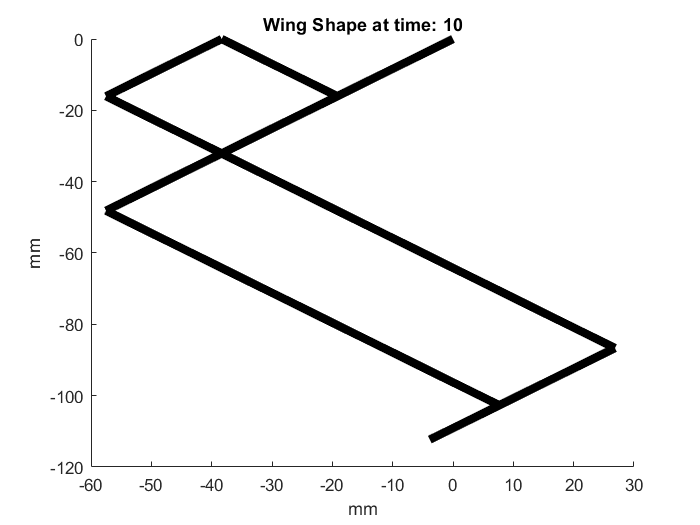

%select the correct timestep
tStep = 10;

%get all the connections
wingConnections = wingShape.AllConnectionLines;

%plot each wing segment together
figure(2)
clf
hold on
for i = 1:size(wingConnections,1)
    plot([wingPointsOverTime2D(1,wingConnections(i,1),tStep),wingPointsOverTime2D(1,wingConnections(i,2),tStep)],...
        [wingPointsOverTime2D(2,wingConnections(i,1),tStep),wingPointsOverTime2D(2,wingConnections(i,2),tStep)],...
        'k','LineWidth',5);
end
xlabel("mm");
ylabel("mm");
title("Wing Shape at time: " + tStep);

%add the tail to the wing points, do this if neccessary
tempPts = zeros([size(wingPointsOverTime2D,1),size(wingPointsOverTime2D,2) + 1,size(wingPointsOverTime2D,3)]);
for i = 1:size(wingPointsOverTime2D,3)
    wingPts = squeeze(wingPointsOverTime2D(:,:,i));
    wingPts = [wingPts, [-100; 0;0]];
    tempPts(:,:,i) = wingPts;
end
wingPointsOverTime2D = tempPts;

tempPts = zeros([size(wingPointsOverTime3D,1),size(wingPointsOverTime3D,2) + 1,size(wingPointsOverTime3D,3)]);
for i = 1:size(wingPointsOverTime3D,3)
    wingPts = squeeze(wingPointsOverTime3D(:,:,i));
    wingPts = [wingPts, [-100; 0;0]];
    tempPts(:,:,i) = wingPts;
end
wingPointsOverTime3D = tempPts;

#### Cost/Evaluation function 1: wing-area over time.

Given inputs: Wing points locations over time, Wing structure connectivity matrix: (which points are connected to each other)

Outputs: Wing area over time

%store the total area of the wing over time
wingAreas = zeros(size(t));

%store the polyshaoes which will represent the wing areas over time
pWingShapes = [];

%go through each wing shape and get the convex hull
for i  = 1:size(t,2)
    wingPts = squeeze(wingPointsOverTime2D(1:2,:,i))';
    [pts,area] = convhull(wingPts);
    wingAreas(i) = area;
    polyPoints = wingPts(pts,:);
    pgon = polyshape(polyPoints);
    pWingShapes = [pWingShapes; pgon];
end

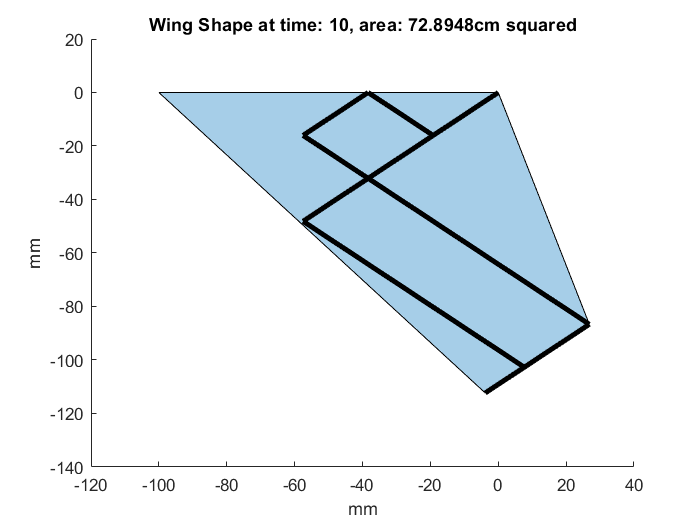

%plot the wing shape at a time
%plot each wing segment together
figure(3)
clf
hold on
plot(pWingShapes(tStep));
hold on
for i = 1:size(wingConnections,1)
    plot([wingPointsOverTime2D(1,wingConnections(i,1),tStep),wingPointsOverTime2D(1,wingConnections(i,2),tStep)],...
        [wingPointsOverTime2D(2,wingConnections(i,1),tStep),wingPointsOverTime2D(2,wingConnections(i,2),tStep)],...
        'k','LineWidth',3);
end
xlabel("mm");
ylabel("mm");
title("Wing Shape at time: " + tStep + ", area: " + wingAreas(tStep)/100 + "cm squared");

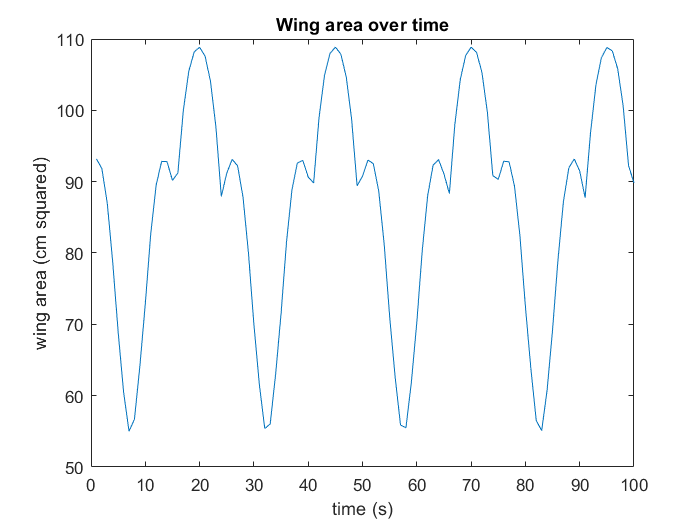

%plot wing area over time
figure(4)
clf
plot(wingAreas/100)
xlabel("time (s)")
ylabel("wing area (cm squared)")
title("Wing area over time")

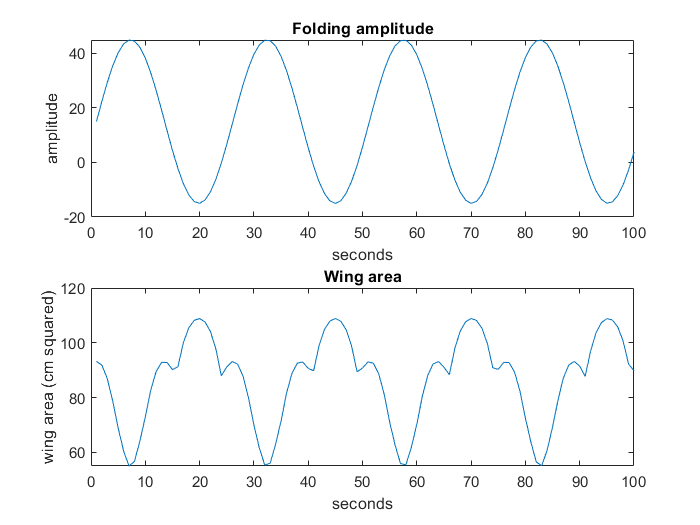

%plot with the folding amplitude included
figure(5)
clf

subplot(2,1,1)
plot(amplitudes)
xlabel('seconds')
ylabel('amplitude')
title("Folding amplitude")

subplot(2,1,2)
plot(wingAreas/100)
xlabel('seconds')
ylabel('wing area (cm squared)')
title("Wing area")

#### Cost/Evaluation function 2: wing cross section length from base to tip over time.

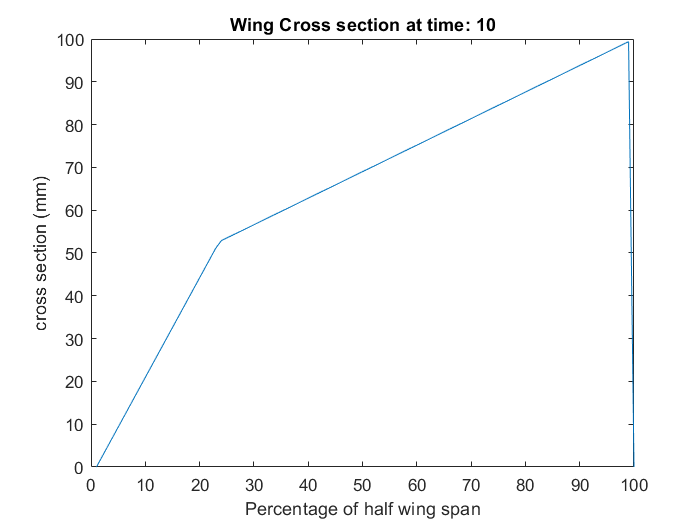

%number of sections for which to compute the wing cross section for
numSections = 100;

%create an array to hold the wing cross section from base to tip over time
%here
crossSectionArray = zeros([length(t) numSections]);

%for each wing shape
for i = 1:size(wingPointsOverTime2D,3)
    %get the wing points for the timestep
    wPoints = squeeze(wingPointsOverTime2D(:,:,i));
    
    %find the min and max x and y points for the wing shape for the timestep
    minY = min(wPoints(2,:));
    maxY = max(wPoints(2,:));
    minX = min(wPoints(1,:));
    maxX = max(wPoints(1,:));
    
    %create a set of "y lines" for which to compute the wing intersection
    %area
    yLines = linspace(minY,maxY,numSections);
    
    %for each Y line, compute the intersection points between that line and
    %the wing, and find the length
    for j = 1:100
        %create the line segment
        lineseg = [minX yLines(j); maxX yLines(j)];
        
        %intersect the line segment with the polyshape
        [in,out] = intersect(pWingShapes(i),lineseg);
        
        %get the difference between the inside points and that it the
        %length, save it
        %note that if in is empty then store a zero
        if isempty(in)
            crossSectionArray(i,j) = 0;
        else 
            crossSectionArray(i,j) = abs(in(2,1) - in(1,1));
        end
        
    end
end
%show the wing cross section over time at the timestep
figure(5)
clf
plot(crossSectionArray(tStep,:));
xlabel("Percentage of half wing span")
ylabel("cross section (mm)")
title("Wing Cross section at time: " + tStep)

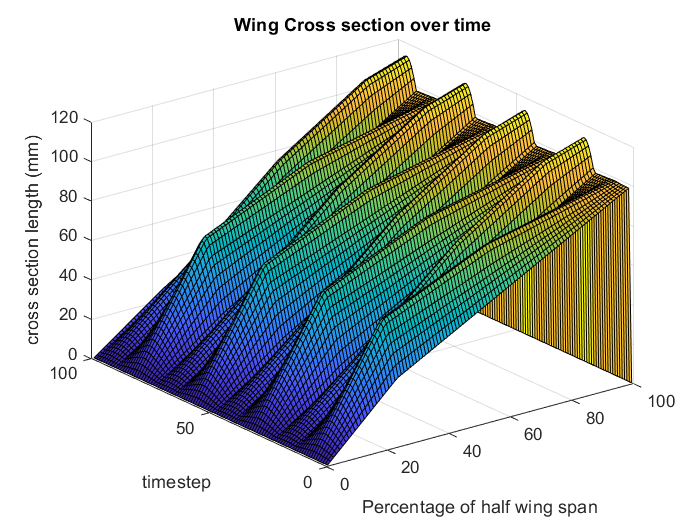

%do a surface plot
[X,Y] = meshgrid(1:100,1:length(t));
figure(6)
clf
surf(X,Y,crossSectionArray);
xlabel("Percentage of half wing span")
ylabel("timestep")
zlabel("cross section length (mm)")
title("Wing Cross section over time")

#### Cost/Evaluation function 3: wing area subtended during upstroke vs downstroke.

%first take the wing flapping stroke and determine when it is going down vs
%when it is going up. To do this use derivatives!
flapAngleDeriv = diff(angles);

%save the wing volumes
wingVolumes = zeros(size(flapAngleDeriv));

%save the actual convex hulls
convexHulls = struct('points',[],'triangles',[]);

%for each derivative, we compute a volume
for i = 1:length(flapAngleDeriv)
    %get the two sets of points
    pointSet1 = squeeze(wingPointsOverTime3D(:,:,i));
    pointSet2 = squeeze(wingPointsOverTime3D(:,:,i+1));
    fullPointsSet = [pointSet1,pointSet2];
    
    %create the convex hull in 3D
    [k,vol] = convhull(fullPointsSet(1,:),fullPointsSet(2,:),fullPointsSet(3,:));
    
    %save the convex hull volume
    wingVolumes(i) = vol;
    
    %save the actual convex hull
    convexHulls(i).points = fullPointsSet;
    convexHulls(i).triangles = k;
end

%plot the sweep volume versus the flapping and folding ampitude
%plot these two
figure(7)
clf
subplot(3,1,1)
plot(angles)
xlabel('seconds')
ylabel('angle')
title("Flapping amplitude (from horizontal)")

subplot(3,1,2)
plot(amplitudes)
xlabel('seconds')
ylabel('amplitude')
title("Folding amplitude")

subplot(3,1,3)
plot(wingVolumes/(1000))
xlabel('seconds')
ylabel('wing volume (cm cubed)')
title("Instantaneous wing volume subtended")
%sum the volumes which have positive and negative derivatives here
downFlap = 0;
upFlap = 0;
for i = 1:length(flapAngleDeriv)
    if flapAngleDeriv(i) > 0
        upFlap = upFlap + wingVolumes(i);
    else
        downFlap = downFlap + wingVolumes(i);
    end
end

%show the upflap and downflap
upFlap/(1000)

ans = 5.8444e+03

downFlap/(1000)

ans = 6.1603e+03

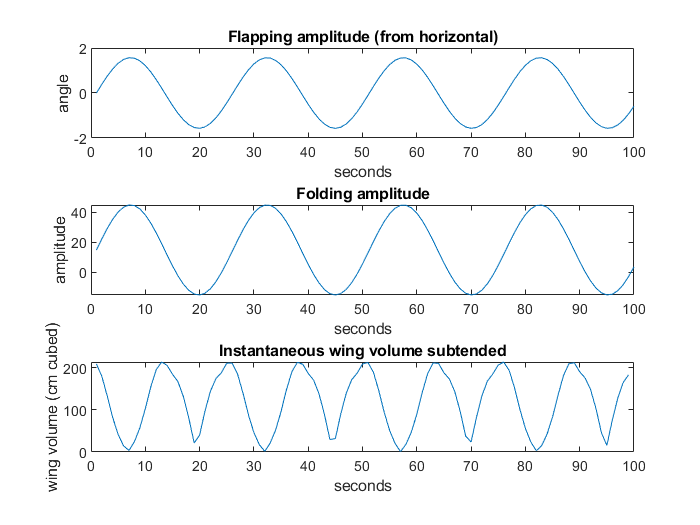

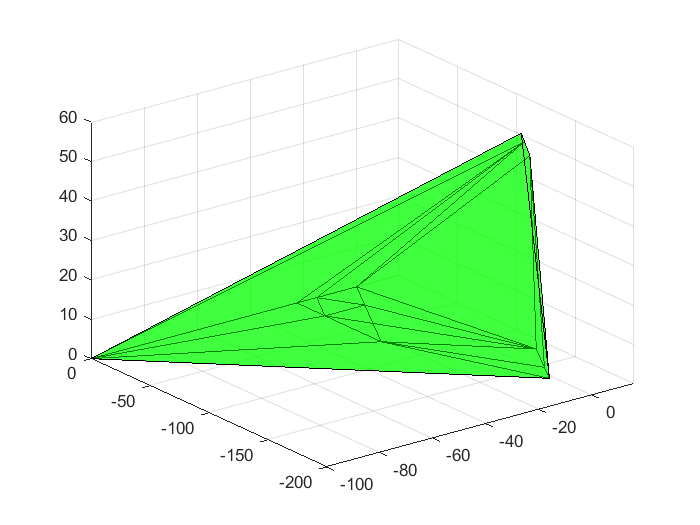

%plot the actual volumes here
figure(8)
clf
hold on
for i = 1:length(flapAngleDeriv)
    clf
    %get the points
    hullPts = convexHulls(i).points;
    
    %if it is a positive derivative plot if red
    if flapAngleDeriv(i) > 0
        %if it is a negative derivative plot in green
        trisurf(convexHulls(i).triangles,hullPts(1,:)',hullPts(2,:)',hullPts(3,:)','FaceColor','green','FaceAlpha',0.5);
    else
        %if it is a negative derivative plot in green
        trisurf(convexHulls(i).triangles,hullPts(1,:)',hullPts(2,:)',hullPts(3,:)','FaceColor','red','FaceAlpha',0.5);
    end
    pause(0.1)
end

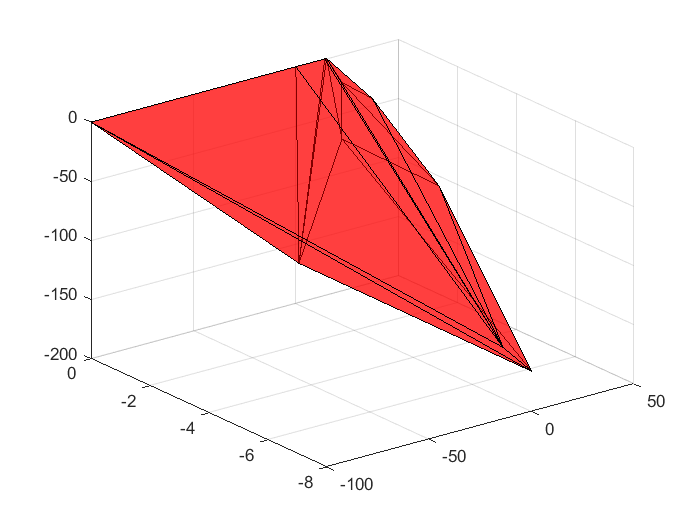

axis equal

#### Cost/Evaluation function 4: induced wing moment from aerodynamic forces.

We can compute the aerodynamic moment by computing the velocity (which varies along the length) and then multiplying it by the thin strip of cross sectional area to get the force distribution and then crossing it with the distance from base to tip to get the moment.

#### Cost/Evaluation function 5: lift/drag/thrust over time using simple airfoil model.

#### Cost/Evaluation function 6: thin airfoil theory ift/drag/thrust over time.